# Tarea filtro notch

Diana Carolina Diaz 20151005010

Nicolas Rodriguez Daza 201510050

Jeison Estiven Garcia 20151005015

## Filtro Notch

La forma mas comun de la funcion de transferencia de un filtro notch es $H(j\omega)=H_{0N}H_N(j\omega)$ donde $H_{0N}$ es una constante de ganacia apropiada  y $H_N$ se muestra a continuacion:


$$H_N(j\omega)=\frac{1-(\omega/\omega_0)^2}{1-(\omega/\omega_0)^2+j(\omega/\omega_0)/Q}$$



$$H_N(s)=\frac{s^2+\omega_0^2}{s^2+\frac{\omega_0}{Q}s+\omega_0^2}$$


De lo cual se puede observar que a frecuencias suficientemente altas y bajas $H_N \longrightarrow 1$ sin embargo para $\frac{\omega }{\omega_0 }=1\;$se tiene que $H_N \longrightarrow 0$. En la figura mostrada a continuacion se muestra la respuesta en frecuencia de un filtro notch y se puede notar que entre mas alta es el factor de calidad del filtro **Q** mas angosta es la banda de rechazo del filtro  notch.

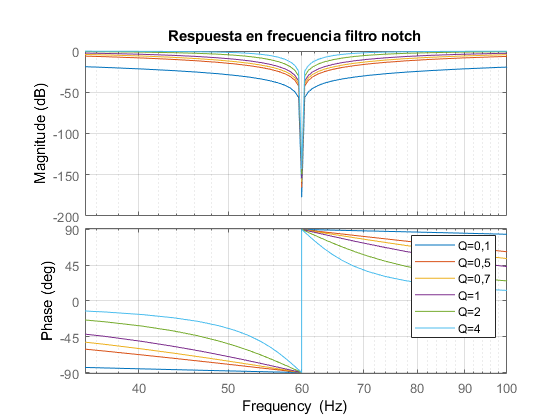

bodeNotch();

En circuito practico no es realizable una notch infinitamente profunda, debido a factores no ideales de los componentes. Ademas es importante tener en cuenta que  $H_N =H_{\mathrm{LP}} +H_{\mathrm{Hp}} =1-H_{\mathrm{BP}}$ que nos brindan formas alternativas de sintetizar la respuesta una vez que se dispone de las otras respuestas.

## Implementación practica del filtro notch

### Filtro KRC rechaza banda

El circuito de la figura consiste en una malla gemela en T y un bloque de ganacia para retroalimentación positivia por medio de la capacitancia superior. Las mallas en T proporcionan trayectoria de baja frecuencia R-R, y la trayectoria de alta frecuencia C-C, que indica que $H\longrightarrow K\;$ en las frecuencias extremas. Sin embargo a frecuencias intermedias, las dos trayectorias brindan ángulos de fase opuestos, que indican una tendencia de las dos señales a cancelarse una con la otra en la entrada del amplificador. Entonces se anticipa una respuesta notch. El analisis de 'ca' del circuito da como funcion de transferencia :

$H_N(s)=K \,\,\frac{s^2+(1/RC)^2}{s^2+\frac{1/RC}{1/(4-2K)}s+(1/RC)^2}$   donde $K=1+\frac{R_B }{R_A }$

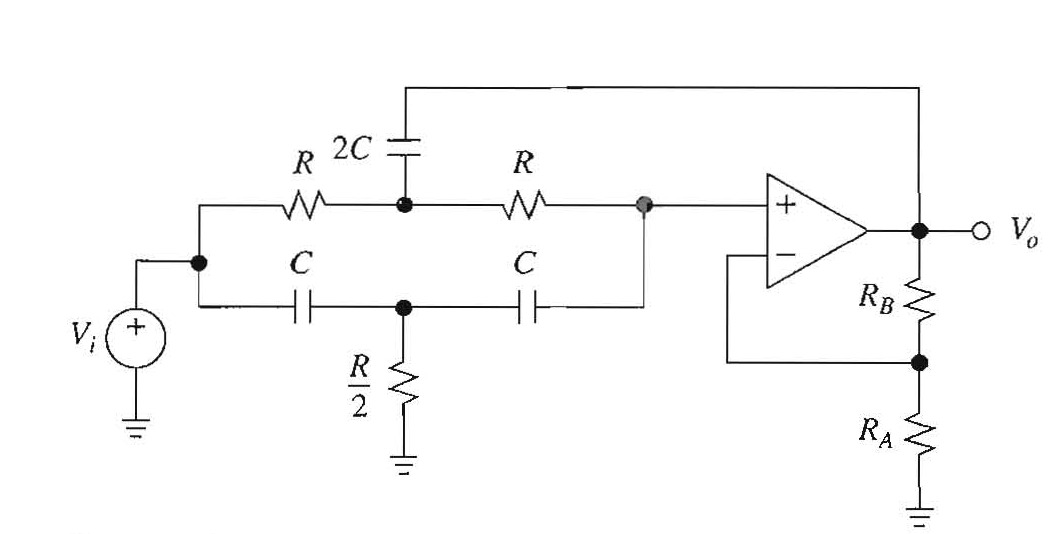

#### Ecuaciones de diseño

A partir de la ecuacion de transferencia del sistema es posible obtener las ecuaciones de diseño del filtro: 


$$\omega_0 =\frac{1}{\mathrm{RC}}$$
       
$$Q=\frac{1}{4-2K}$$
     
$$K=1+\frac{R_B }{R_A }$$


## Simulacion 

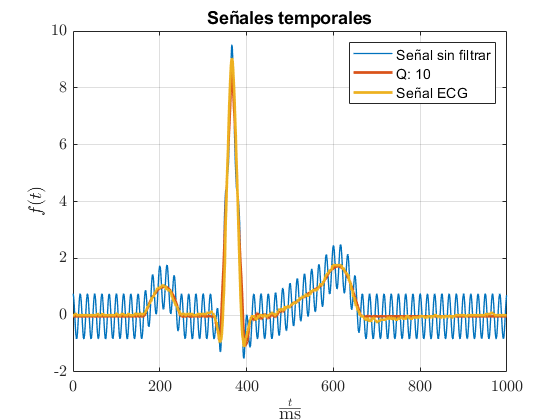

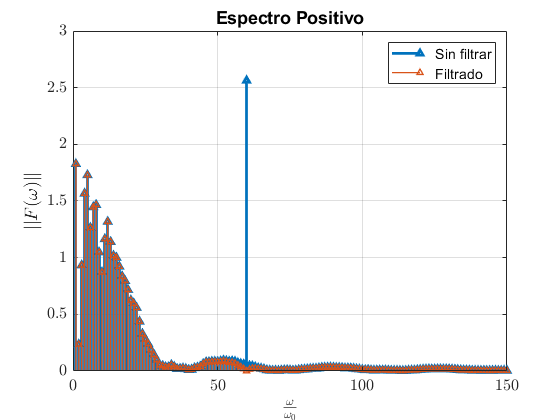

magnitudruido = 0.8;
Q = 10;
comparacionespectronotch(magnitudruido,Q)

# Referencias

- Franco, S. (2005). *Diseño con amplificadores operacionales y circuitos integrados analogicos* (Vol. 3a). Mexico D.F: Mc Graw Hill.

# Funciones

function []=bodeNotch()
    syms s
    s=tf('s');
    wo=2*pi*60;
    opts = bodeoptions('cstprefs');
    opts.FreqUnits = 'Hz';
    opts.Xlim=[35 100];
    
    for Q=[0.1,0.5,0.7,1,2,4]
        Hn=((s^2+wo^2)/(s^2+s*wo/Q+wo^2));   
        bode(Hn,opts);
        hold on
    end
    grid on
    hold off
    title('Respuesta en frecuencia filtro notch')
    legend('Q=0,1','Q=0,5','Q=0,7','Q=1','Q=2','Q=4');
end

function [] = comparacionespectronotch(magnitudruido,Q)
    armonicas = 150; 
    a = csvread('ECG1kHz.csv',2,0);
    f = a(1200:2199,2) + 4;
    dc = mean(f);
    
    T = 1000;
    
    x = [0,164,211,247,326,339,366,394,413,463,575,611,640,663,999];
    y = [0,0,1.04,0,0,-0.96,9.04,-1.12,0,0,1.12,1.76,1.12,0,0];
    
    t = linspace(0,T-1,1000);
    dx = diff(x);
    dy = diff(y);
    m = dy./dx;
    dm = diff(m);
    n = 1:armonicas;
    
    cn = ((2*dy(2)/dx(2))*exp(-i*n*2*pi*x(2)/T)...
    + (2*dy(2)/dx(3))*exp(-i*n*2*pi*x(4)/T)...
    + dm(4)*exp(-i*n*2*pi*x(5)/T)...
    + dm(5)*exp(-i*n*2*pi*x(6)/T)...
    + dm(6)*exp(-i*n*2*pi*x(7)/T)...
    + dm(7)*exp(-i*n*2*pi*x(8)/T)...
    + dm(8)*exp(-i*n*2*pi*x(9)/T)...
    + dm(9)*exp(-i*n*2*pi*x(10)/T)...
    - dm(9)*exp(-i*n*2*pi*x(11)/T)...
    + (2*dy(11)/dx(11))*exp(-i*n*2*pi*x(11)/T)...
    + (2*dy(11)/dx(12))*exp(-i*n*2*pi*x(13)/T)...
    + m(13)*exp(-i*n*2*pi*x(13)/T)...
    - m(13)*exp(-i*n*2*pi*x(14)/T))...% fin de las rampas
    ./(-n.*n.*4*pi*pi/T)...
    + ((-2*dy(2)/dx(2)^2)*exp(-i*n*2*pi*x(2)/T)...
    + (-2*dy(2)/dx(3)^2 + 2*dy(2)/dx(2)^2)*exp(-i*n*2*pi*x(3)/T)...
    + (2*dy(2)/dx(3)^2)*exp(-i*n*2*pi*x(4)/T)...
    + (-2*dy(11)/dx(11)^2)*exp(-i*n*2*pi*x(11)/T)...
    + (-2*dy(11)/dx(12)^2 + 2*dy(11)/dx(11)^2)*exp(-i*n*2*pi*x(12)/T)...
    + (2*dy(11)/dx(12)^2)*exp(-i*n*2*pi*x(13)/T))...%fin de las parábolas
    ./(-i*n.*n.*n.*8*pi*pi*pi/(T*T))...
    ;
    
    cn(60) = cn(60) + magnitudruido/2;
    
    an = 2*real(cn);
    bn = -2*imag(cn);
     
    serie = dc;
    for k=1:length(n)
         serie = serie + an(k)*cos(k*2*pi*t/T)+ bn(k)*sin(k*2*pi*t/T);
    end
    
    figure(2)
    plot(t,serie,'LineWidth',1);
    grid on;
    set(gca,'FontSize',12);
    set(gca,'TickLabelInterpreter','latex');
    set(gcf,'Color','white');
    title('Señales temporales');
    xlabel('$\frac{t}{\textrm{ms}}$','Interpreter','latex');
    ylabel('$f(t)$','Interpreter','latex');
    
    figure(3)
    stem(1:armonicas,2*pi*abs(cn),'^',...
        'LineWidth',2,'MarkerSize',4);
    grid on;
    set(gca,'FontSize',12);
    set(gca,'TickLabelInterpreter','latex');
    set(gcf,'Color','white');
    title('Espectro Positivo');
    xlabel('$\frac{\omega}{\omega_0}$','Interpreter','latex');
    ylabel('$||F(\omega)||$',...
        'Interpreter','latex');
    
    figure(2)  
    hold on;

    
    % Filtro Notch
    s=2*pi*n*1i;
    wo=2*pi*60;
    HN = (s.^2+wo^2)./(s.^2+s*wo/Q+wo^2);
    cn = cn.*(HN);
    
    an = 2*real(cn);
    bn = -2*imag(cn);
     
    serie = dc;
    for k=1:length(n)
         serie = serie + an(k)*cos(k*2*pi*t/T)+ bn(k)*sin(k*2*pi*t/T);
    end
    plot(t,serie,'LineWidth',2);
    plot(t,f,'LineWidth',2);
    hold off;
    legend({'Señal sin filtrar',['Q: ',num2str(Q)],'Señal ECG'},...
        'Location','northeast');
    
    figure(3)
    hold on;
    stem(1:armonicas,2*pi*abs(cn),'^',...
        'LineWidth',1,'MarkerSize',4);  
    hold off;
    legend('Sin filtrar','Filtrado');
    
end